# Signal and noise per PC, supplement

org = Org; org.init;

load eigen_snr_crossval_save.mat

filt = SessManager.highqual_filt_from_usable;
mouse_ = org.mouse(filt);
dp2_test = dp2_test(filt);
dp2_train = dp2_train(filt);
noise_test = noise_test(filt);
noise_train = noise_train(filt);
signal_test = signal_test(filt);
signal_train = signal_train(filt);

[dp2_test_agg, dp2_test_agg_sem] = jagged_agg(dp2_test);
[dp2_train_agg, dp2_train_agg_sem] = jagged_agg(dp2_train);

[signal_test_agg, signal_test_agg_sem] = jagged_agg(signal_test);
[signal_train_agg, signal_train_agg_sem] = jagged_agg(signal_train);

[noise_test_agg, noise_test_agg_sem] = jagged_agg(noise_test);
[noise_train_agg, noise_train_agg_sem] = jagged_agg(noise_train);

dp2_test_agg_mean = squeeze(mean(dp2_test_agg,1));
dp2_test_agg_mean_sem = squeeze(sqrt(mean(dp2_test_agg_sem.^2,1) + (std(dp2_test_agg,0,1)./sqrt(size(dp2_test_agg,1))).^2));

dp2_train_agg_mean = squeeze(mean(dp2_train_agg,1));
dp2_train_agg_mean_sem = squeeze(sqrt(mean(dp2_train_agg_sem.^2,1) + (std(dp2_train_agg,0,1)./sqrt(size(dp2_train_agg,1))).^2));


signal_test_agg_mean = squeeze(mean(signal_test_agg,1));
signal_test_agg_mean_sem = squeeze(sqrt(mean(signal_test_agg_sem.^2,1) + (std(signal_test_agg,0,1)./sqrt(size(signal_test_agg,1))).^2));

signal_train_agg_mean = squeeze(mean(signal_train_agg,1));
signal_train_agg_mean_sem = squeeze(sqrt(mean(signal_train_agg_sem.^2,1) + (std(signal_train_agg,0,1)./sqrt(size(signal_train_agg,1))).^2));


noise_train_agg_mean = squeeze(mean(noise_train_agg,1));
noise_train_agg_mean_sem = squeeze(sqrt(mean(noise_train_agg_sem.^2,1) + (std(noise_train_agg,0,1)./sqrt(size(noise_train_agg,1))).^2));

noise_test_agg_mean = squeeze(mean(noise_test_agg,1));
noise_test_agg_mean_sem = squeeze(sqrt(mean(noise_test_agg_sem.^2,1) + (std(noise_test_agg,0,1)./sqrt(size(noise_test_agg,1))).^2));

## Aggregated across all sessions

figure('Position', [272 637 1139 306]);

### SNR

subplot(1,3,1);
H_TR = serrorbar(median(dp2_train_agg_mean), median(dp2_train_agg_mean_sem) * 1.96, 'k:');
hold on;
H_TE = serrorbar(median(dp2_test_agg_mean), median(dp2_test_agg_mean_sem) * 1.96, 'b');
xlabel 'PC index'
ylabel 'Eigen SNR [All sessions]'
yl_ = ylim;

[~, argmax_pc_snr] = max(median(dp2_test_agg_mean));
med_dp2_test = median(dp2_test_agg_mean);
fprintf('Sum of dp2 from 1 to %d (the max) = %f\n which is %f%% of the total %f\n', argmax_pc_snr, sum(med_dp2_test(1:argmax_pc_snr)), 100 * sum(med_dp2_test(1:argmax_pc_snr))/sum(med_dp2_test), sum(med_dp2_test));

Sum of dp2 from 1 to 6 (the max) = 0.332688
 which is 8.381813% of the total 3.969170


l_ = line([argmax_pc_snr argmax_pc_snr], yl_, 'Color', 'r');

x_ = median(dp2_test_agg_mean);
cum_x_ = cumsum(x_) ./ sum(x_);
ix_most = find(cum_x_ >= 0.95, 1);
l2_ = line([ix_most ix_most], yl_, 'Color', 'g');


legend([H_TR.mainLine, H_TE.mainLine, l_, l2_], 'Train', 'Test',...
    sprintf('Max SNR (PC%d)', argmax_pc_snr),...
    sprintf('95%% SNR (PC1-%d)', ix_most));
legend boxoff
legend location north

### Signal

subplot(1,3,2);
H_TR = serrorbar(median(signal_train_agg_mean), median(signal_train_agg_mean_sem) * 1.96, 'k:');
hold on;
H_TE = serrorbar(median(signal_test_agg_mean), median(signal_test_agg_mean_sem) * 1.96, 'b');
xlabel 'PC index'
ylabel 'Eigen Signal [All sessions]'

[~, argmax_pc_signal] = max(median(signal_test_agg_mean));
l_ = line([argmax_pc_signal argmax_pc_signal], ylim, 'Color', 'r');

x_ = median(signal_test_agg_mean);
cum_x_ = cumsum(x_) ./ sum(x_);
ix_most = find(cum_x_ >= 0.95, 1);
l2_ = line([ix_most ix_most], ylim, 'Color', 'g');

legend([H_TR.mainLine, H_TE.mainLine, l_, l2_], 'Train', 'Test',...
    sprintf('Max Signal (PC%d)', argmax_pc_signal),...
    sprintf('95%% Signal (PC1-%d)', ix_most));
legend boxoff
legend location north

### Noise

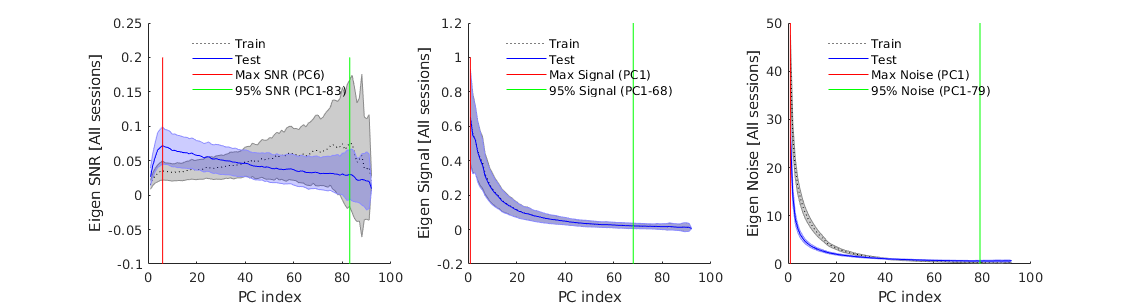

subplot(1,3,3);
H_TR = serrorbar(median(noise_train_agg_mean), median(noise_train_agg_mean_sem) * 1.96, 'k:');
hold on;
H_TE = serrorbar(median(noise_test_agg_mean), median(noise_test_agg_mean_sem) * 1.96, 'b');
xlabel 'PC index'
ylabel 'Eigen Noise [All sessions]'

[~, argmax_pc_noise] = max(median(noise_test_agg_mean));
l_ = line([argmax_pc_noise argmax_pc_noise], ylim, 'Color', 'r');

x_ = median(noise_test_agg_mean);
cum_x_ = cumsum(x_) ./ sum(x_);
ix_most = find(cum_x_ >= 0.95, 1);
l2_ = line([ix_most ix_most], ylim, 'Color', 'g');

legend([H_TR.mainLine, H_TE.mainLine, l_, l2_], 'Train', 'Test',...
    sprintf('Max Noise (PC%d)', argmax_pc_noise),...
    sprintf('95%% Noise (PC1-%d)', ix_most));
legend boxoff
legend location north
Utils.printto('events_figs/f3_supplements', 'aggregated_eigen_SNR_signal_noise.pdf');

## Disaggregated by mouse

### SNR

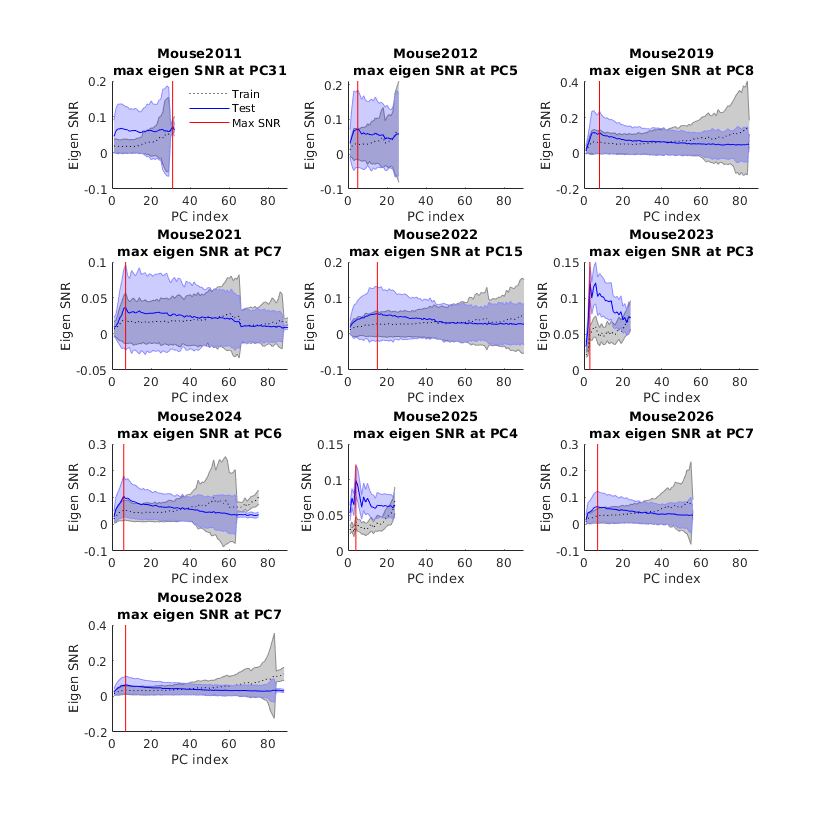

%max_pos = [0.0010    0.0383    2.1333    1.0907]*1e3;
max_pos = [2542         103         839         827];
figure('Position', max_pos);

variable_name = 'eigen SNR';

my_mice = unique(mouse_);
for m_i = 1:numel(my_mice)
    my_mouse = my_mice{m_i};
    [m_tr, s_tr] = quick_agg(dp2_train(strcmp(mouse_,my_mouse)));
    [m_te, s_te] = quick_agg(dp2_test(strcmp(mouse_,my_mouse)));
    subplot(4,3,m_i);
    [a_, b_] = quick_plot(m_tr, s_tr, m_te, s_te, m_i, 'SNR');
    %title(sprintf('%s, max at PC%d, 95%% at PC1-%d', my_mouse, a_, b_));
    title(sprintf('%s\nmax %s at PC%d', my_mouse, variable_name, a_));
    xlim([0 90]);
end
Utils.printto('events_figs/f3_supplements', 'eigen_SNR_by_mouse.pdf');

### Signal

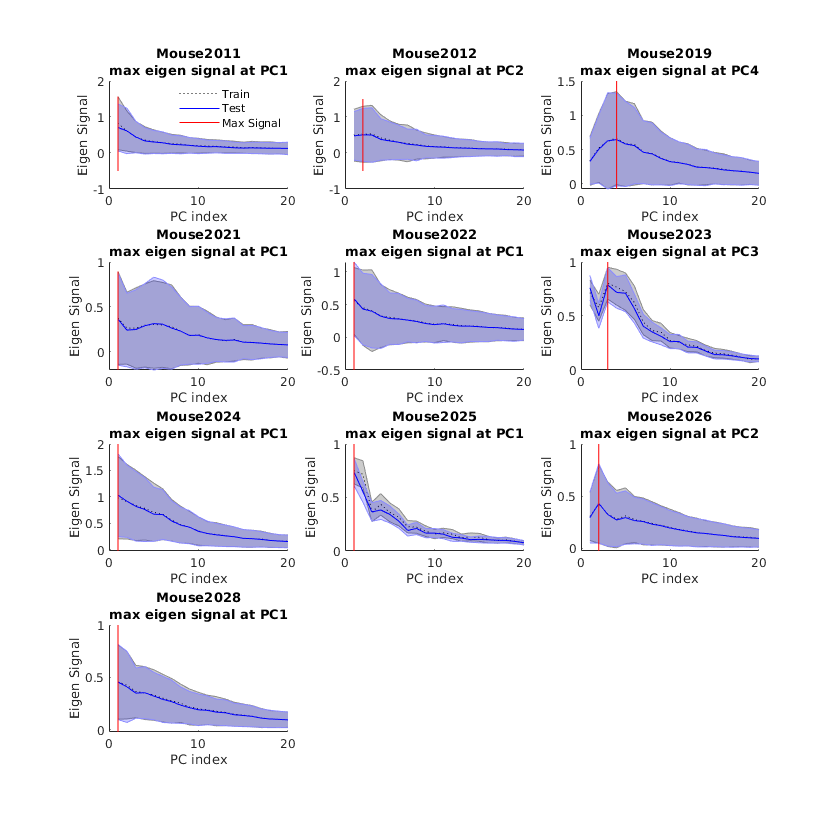

figure('Position', max_pos);

variable_name = 'eigen signal';

my_mice = unique(mouse_);
for m_i = 1:numel(my_mice)
    my_mouse = my_mice{m_i};
    [m_tr, s_tr] = quick_agg(signal_train(strcmp(mouse_,my_mouse)));
    [m_te, s_te] = quick_agg(signal_test(strcmp(mouse_,my_mouse)));
    subplot(4,3,m_i);
    [a_, b_] = quick_plot(m_tr, s_tr, m_te, s_te, m_i, 'Signal');
    %title(sprintf('%s, max at PC%d, 95%% at PC1-%d', my_mouse, a_, b_));
    title(sprintf('%s\nmax %s at PC%d', my_mouse, variable_name, a_));
    xlim([0 20]);
end
Utils.printto('events_figs/f3_supplements', 'eigen_signal_by_mouse.pdf');

### Noise

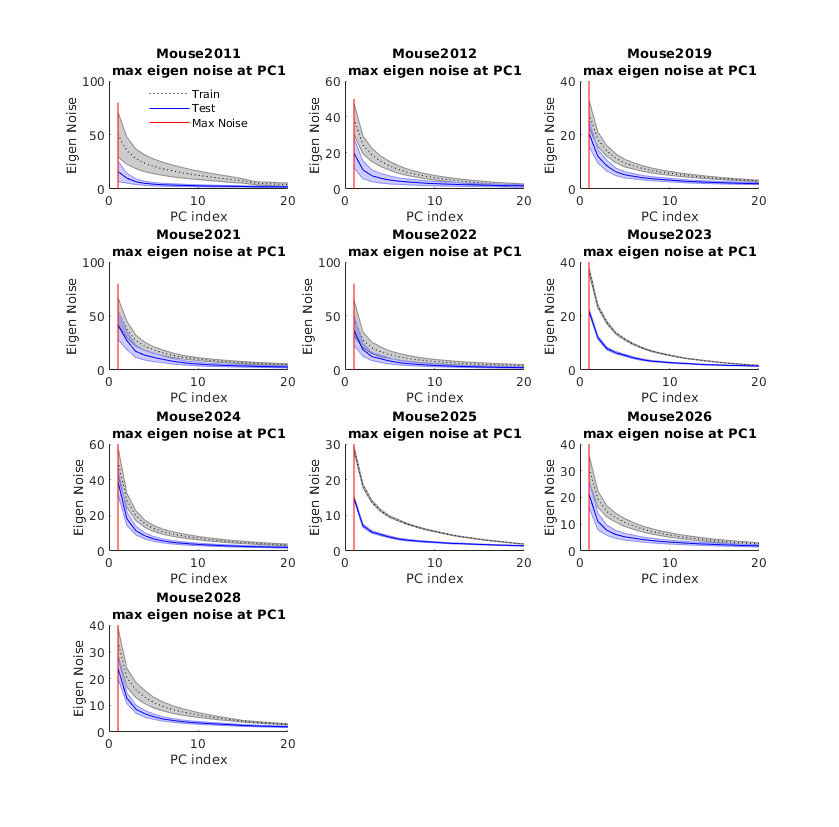

figure('Position', max_pos);

variable_name = 'eigen noise';

my_mice = unique(mouse_);
for m_i = 1:numel(my_mice)
    my_mouse = my_mice{m_i};
    [m_tr, s_tr] = quick_agg(noise_train(strcmp(mouse_,my_mouse)));
    [m_te, s_te] = quick_agg(noise_test(strcmp(mouse_,my_mouse)));
    subplot(4,3,m_i);
    [a_, b_] = quick_plot(m_tr, s_tr, m_te, s_te, m_i, 'Noise');
    %title(sprintf('%s, max at PC%d, 95%% at PC1-%d', my_mouse, a_, b_));
    title(sprintf('%s\nmax %s at PC%d', my_mouse, variable_name, a_));
    xlim([0 20]);
end
Utils.printto('events_figs/f3_supplements', 'eigen_noise_by_mouse.pdf');

## Area between cos^2 overlaps

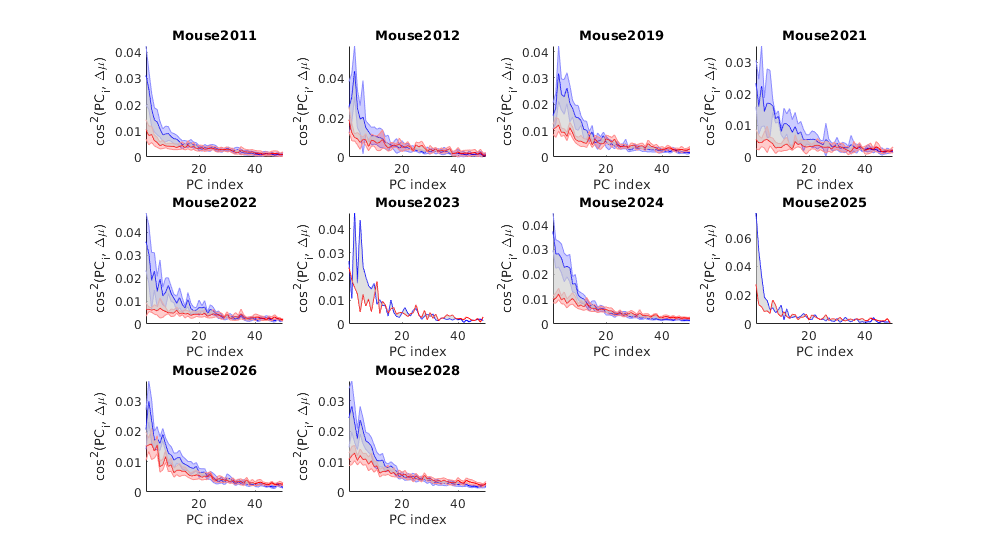

MAX_DIM = 40;
figure('Position', [2302 322 987 560]);
m_list = SessManager.highqual_mice;
for i = 1:numel(m_list)
    subplot(3,4,i);
    [l2, l2_sem] = org.mouse_med_bins('loadings2', {m_list{i},'restrict'});
    [l2_s, l2_s_sem] = org.mouse_med_bins('loadings_shuf2', {m_list{i},'restrict'});
    serrorbar(l2, l2_sem*1.96, 'b');
    hold on;
    serrorbar(l2_s, l2_s_sem*1.96, 'r');
    ylim([0 Inf]);
    xlim([1 50]);
    patch([1:MAX_DIM, MAX_DIM:-1:1],...
        [l2(1:MAX_DIM)', l2_s(MAX_DIM:-1:1)'],...
        [1 1 1]*0.8, 'FaceAlpha', 0.6, 'EdgeColor', 'none');

    xlabel 'PC index'
    ylabel 'cos^2(PC_i, \Delta\mu)'
    title(m_list{i});
end
Utils.printto('events_figs/f3_supplements', 'area_between_cos2_by_mouse.pdf');

## Functions

function [argmax_pc_snr, ix_most] = quick_plot(dp2_train_agg_mean, dp2_train_agg_mean_sem, dp2_test_agg_mean, dp2_test_agg_mean_sem, i, label)
H_TR = serrorbar(median(dp2_train_agg_mean), median(dp2_train_agg_mean_sem) * 1.96, 'k:');
hold on;
H_TE = serrorbar(median(dp2_test_agg_mean), median(dp2_test_agg_mean_sem) * 1.96, 'b');
xlabel 'PC index'
ylabel(sprintf('Eigen %s',label));

[~, argmax_pc_snr] = max(median(dp2_test_agg_mean));
l_ = line([argmax_pc_snr argmax_pc_snr], ylim, 'Color', 'r');

x_ = median(dp2_test_agg_mean);
cum_x_ = cumsum(x_) ./ sum(x_);
ix_most = find(cum_x_ >= 0.95, 1);
%l2_ = line([ix_most ix_most], ylim, 'Color', 'g');

if i == 1
    legend([H_TR.mainLine, H_TE.mainLine, l_], 'Train', 'Test',...
        sprintf('Max %s', label));%,...
    %sprintf('95%% %s (PC1-%d)', label, ix_most));
    legend boxoff
    legend location best
end
end


function [m, s] = quick_agg(X)
[dp2_test_agg, dp2_test_agg_sem] = jagged_agg(X);
%[dp2_train_agg, dp2_train_agg_sem] = jagged_agg(dp2_train);

%mean over random samples
m = squeeze(mean(dp2_test_agg,1));
s = squeeze(sqrt(mean(dp2_test_agg_sem.^2,1) + (std(dp2_test_agg,0,1)./sqrt(size(dp2_test_agg,1))).^2));


%dp2_train_agg_mean = squeeze(mean(dp2_train_agg,1));
%dp2_train_agg_mean_sem = squeeze(sqrt(mean(dp2_train_agg_sem.^2,1) + (std(dp2_train_agg,0,1)./sqrt(size(dp2_train_agg,1))).^2));
end


function [m, s] = jagged_agg(X) %jagged on dim 3
N = length(X);
max_dim = max(cellfun(@(x)size(x,3), X));
Y = cell(1,max_dim);
for i = 1:max_dim
    for j = 1:N
        my_max_dim = size(X{j},3);
        if i > my_max_dim
            continue;
        end
        Y{i}{end+1} = X{j}(:,:,i);
    end
end

for i = 1:max_dim
    C = cat(3, Y{i}{:});
    num_samples = size(C,3);
    m(:,:,i) = mean(C,3);
    s(:,:,i) = std(C,0,3)./sqrt(num_samples);
end
end